Seeing what kids of effect that performing changes to the color channel has on the images when recombind

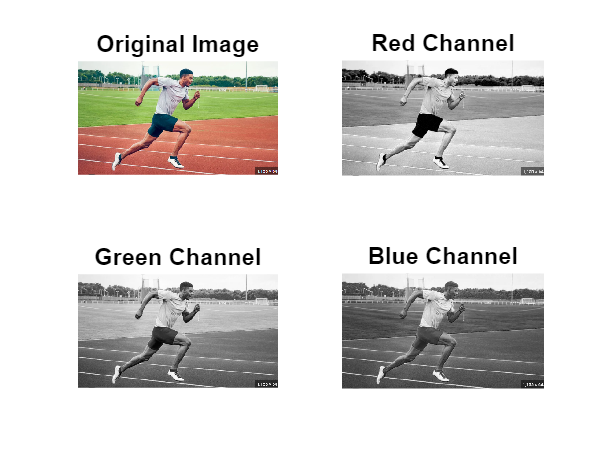

% Read the image
img = imread("running.PNG");

% Split the image into its RGB channels
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

% Display the original image and its RGB channels
figure;
subplot(2,2,1);
imshow(img);
title('Original Image');
subplot(2,2,2);
imshow(R);
title('Red Channel');
subplot(2,2,3);
imshow(G);
title('Green Channel');
subplot(2,2,4);
imshow(B);
title('Blue Channel');

To do this i applied hiseq to each channel to and recombined the rgb channes to see how it affects the final image

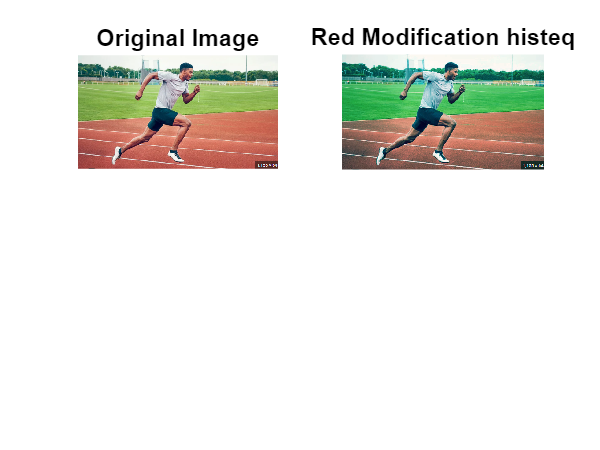

close
figure;
subplot(2,2,1);
R_histeq=histeq(R);
new_imgR = cat(3,R_histeq,G,B);
imshow(img);
title('Original Image');
subplot(2,2,2);
imshow(new_imgR);
title('Red Modification histeq');

imadjust() applied to the green channel

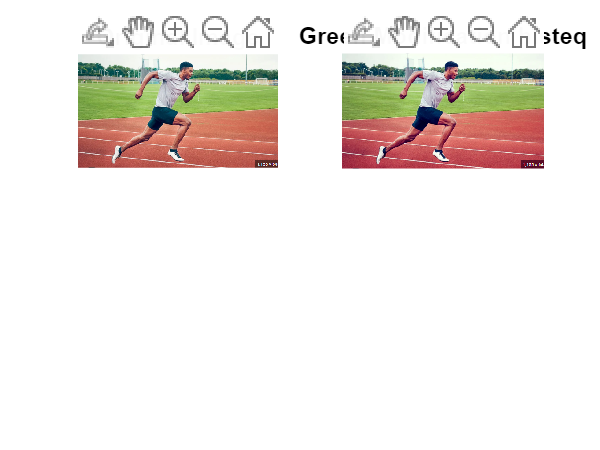

close
figure;
G_histeq=imadjust(G);
new_imgG = cat(3,R,G_histeq,B);
subplot(2,2,1);
imshow(img);
title('Original Image');
subplot(2,2,2);
imshow(new_imgG);
title('Green Modification histeq');

adapthisteq applied to the green channel

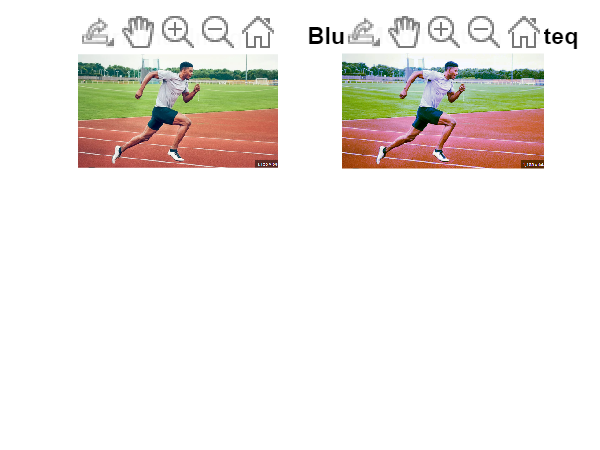

close
figure;
B_histeq=histeq(B);
new_imgB = cat(3,R,G,B_histeq);
subplot(2,2,1);
imshow(img);
title('Original Image ');
subplot(2,2,2);
imshow(new_imgB);
title('Blue Modification histeq');

Finally i will combine all the modifiend rgb channes to se how the final image looks

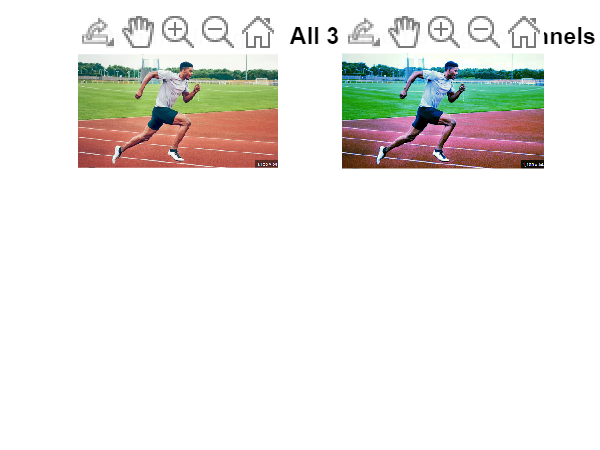

close
img_RGB_mod= cat(3,R_histeq,G_histeq,B_histeq);
figure;
subplot(2,2,1);
imshow(img);
title("Original image");
subplot(2,2,2);
imshow(img_RGB_mod);
title("All 3 modified rgb channels");